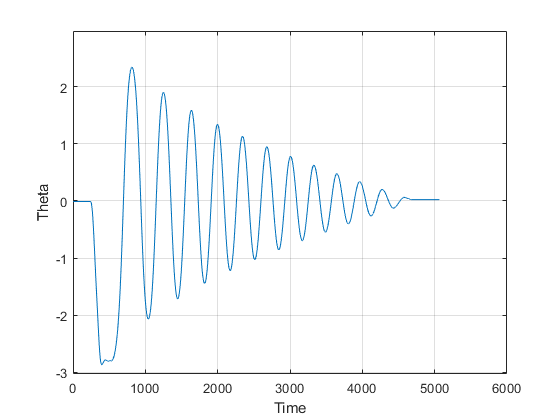

theta = dane_NN_test2.signals(1).values;
time = dane_NN_test2.time;

figure
plot(theta)
xlabel('Time')
ylabel('Theta')
grid on

Zostaly podziolone dane zgodnie ze teorią przedstawioną na labolatoriach

y_begin_sample = 702;
y_end_sample = 4802;


training_data_input_1 = theta(y_begin_sample-2:y_end_sample-2)

training_data_input_1 =     0.0971
    0.1348
    0.1725
    0.2099
    0.2472
    0.2846
    0.3220
    0.3588
    0.3958
    0.4323


training_data_input_2 = theta(y_begin_sample-1:y_end_sample-1)

training_data_input_2 =     0.1348
    0.1725
    0.2099
    0.2472
    0.2846
    0.3220
    0.3588
    0.3958
    0.4323
    0.4687


training_data_output = theta(y_begin_sample:y_end_sample)

training_data_output =     0.1725
    0.2099
    0.2472
    0.2846
    0.3220
    0.3588
    0.3958
    0.4323
    0.4687
    0.5049



x_train = [training_data_input_1'; training_data_input_2']

x_train =     0.0971    0.1348    0.1725    0.2099    0.2472    0.2846    0.3220    0.3588    0.3958    0.4323    0.4687    0.5049    0.5410    0.5765    0.6120    0.6475    0.6824    0.7172    0.7518    0.7860    0.8200    0.8536    0.8869    0.9205    0.9532    0.9852    1.0166    1.0487    1.0798    1.1106    1.1410    1.1712    1.2007    1.2302    1.2592    1.2881    1.3160    1.3440    1.3710    1.3980    1.4244    1.4508    1.4762    1.5017    1.5268    1.5513    1.5755    1.5991    1.6223    1.6453
    0.1348    0.1725    0.2099    0.2472    0.2846    0.3220    0.3588    0.3958    0.4323    0.4687    0.5049    0.5410    0.5765    0.6120    0.6475    0.6824    0.7172    0.7518    0.7860    0.8200    0.8536    0.8869    0.9205    0.9532    0.9852    1.0166    1.0487    1.0798    1.1106    1.1410    1.1712    1.2007    1.2302    1.2592    1.2881    1.3160    1.3440    1.3710    1.3980    1.4244    1.4508    1.4762    1.5017    1.5268    1.5513    1.5755    1.5991    1.6223    1.645

y_train = training_data_output'

y_train =     0.1725    0.2099    0.2472    0.2846    0.3220    0.3588    0.3958    0.4323    0.4687    0.5049    0.5410    0.5765    0.6120    0.6475    0.6824    0.7172    0.7518    0.7860    0.8200    0.8536    0.8869    0.9205    0.9532    0.9852    1.0166    1.0487    1.0798    1.1106    1.1410    1.1712    1.2007    1.2302    1.2592    1.2881    1.3160    1.3440    1.3710    1.3980    1.4244    1.4508    1.4762    1.5017    1.5268    1.5513    1.5755    1.5991    1.6223    1.6453    1.6676    1.6895


Następnie zostala wytrenowana siec neuronowa:

net = feedforwardnet(2, 'trainlm');
net = train(net, x_train, y_train);
view(net);
y_net = net(x_train);
perf = perform(net,y_train, y_net)  

perf = 7.7823e-08

net = feedforwardnet(2, 'trainlm');
net = train(net, x_train, y_train);

y_net = net(x_train);


sample_time = 0.01;
perf = perform(net,y_train, y_net)

perf = 7.8305e-08

gensim(net, sample_time)

ans = 'untitled1'

figure();
hold on
plot(time, y_train)
plot(time, y_net)
hold off
legend("Dane treningowe", 'Model sieci neuronowej')
xlabel('Time [s]')
ylabel('Theta [rad]')
title('Porownanie danych treningowych')
grid on

err = immse(y_train, y_net)
err = y_net-y_train
err_degree = err * 180/pi
figure;
plot(err)

figure;
plot(err_degree)


layers = 1:4;
layers_test = zeros(length(layers), length(training_data_output));
for i=layers
    net = feedforwardnet(i, 'trainlm');
    net = train(net, x_train, y_train);

    y_net = net(x_train);
    layers_test(i, :) = y_net;
    perf = perform(net,y_train, y_net)
end

err = layers_test - y_net;
hold on
plot(err(1, :))
plot(err(2, :))
plot(err(3, :))
plot(err(4, :))
hold off
legend('1 Hidden Layer', '2 Hidden Layer', '3 Hidden Layer', '4 Hidden Layer')

y_test_begin_sample = 500;
y_test_end_sample = 1000;


training_data_input_1 = theta(y_begin_sample-2:y_end_sample-2)
training_data_input_2 = theta(y_begin_sample-1:y_end_sample-1)
training_data_output = theta(y_begin_sample:y_end_sample)